# Maximizing Solar Panel Output for a Fixed Area

In this project, our team **Solar Panel Team #3** designed a solution to identify the **optimal tilt angle** and **optimal aspect ratio** of a solar panel to deliver the **maximal energy output** given environmental constraints. Additionally this project maps the optimal energy output onto a surf plot to illustrate how energy output is dependent on tilt angle and aspect ratio. 

Team: Hector Valenzuela, Leo Kuraoka, and Ty Schoevers

## Model 3: Time Optimization Variable

This project uses MATLAB to figure out the optimal tilt angle, aspect ratio, and time of day for a solar panel with a fixed area of 2 m², using a problem-based optimization workflow to maximize a simplified energy output model.

clear;
clc;
close all;

## Break Down the Problem

**Problem Statement**

Find the tilt angle θ, aspect ratio r, and time of day t that maximize the modeled energy output of a solar panel with a fixed area of 2 m².

The panel tilt angle must satisfy:

0° ≤ θ ≤ 90°

The aspect ratio must satisfy:

0.5 ≤ r ≤ 4

The time of day must satisfy:

6 ≤ t ≤ 18

where:

- t = 6 is 6 AM 

- t = 12 is 12 PM 

- t = 18 is 6 PM 

The project needs to use MATLAB's problem-based optimization workflow, produce a 3D surface plot, and print out the optimal tilt angle, aspect ratio, time, and max energy output.

**Proposed Solution**

Start from the original energy model and extend it with a time-dependent sunlight factor. From there, set up bounded optimization variables, solve for the max of the energy function, and evaluate the model over a meshgrid so we can actually visualize it.

Roughly, the steps are: define the panel area and efficiency functions, define the sunlight intensity function, add the time factor, combine everything into one energy model, set up the optimization problem and variables, solve for the optimal θ, r, and t, plot the energy surface at the optimized time, then print and interpret the results.

**Challenges**

Getting the degree-based trig functions to behave was one issue, since MATLAB's optimization variables don't play nice with `cosd`/`sind` the way regular numeric arrays do, so those had to be rewritten with `cos`/`sin` and a manual degrees-to-radians conversion. Keeping the plotting version of the equations consistent with the optimization version was another thing we had to double check, along with making sure everything used element-wise operations once we started working with grids of values.

Adding a third variable (time) without blowing up the structure of the original two-variable model was also tricky. A normal 3D surface plot can only really show two variables at once, so time gets fixed at its optimal value whenever we're plotting tilt angle against aspect ratio.

## Task 1: Define the Objective Function

The objective function calculates the modeled energy output based on panel area, tilt angle, sunlight intensity, aspect ratio, and time of day. Basically E(θ,r) from the original model became E(θ,r,t).

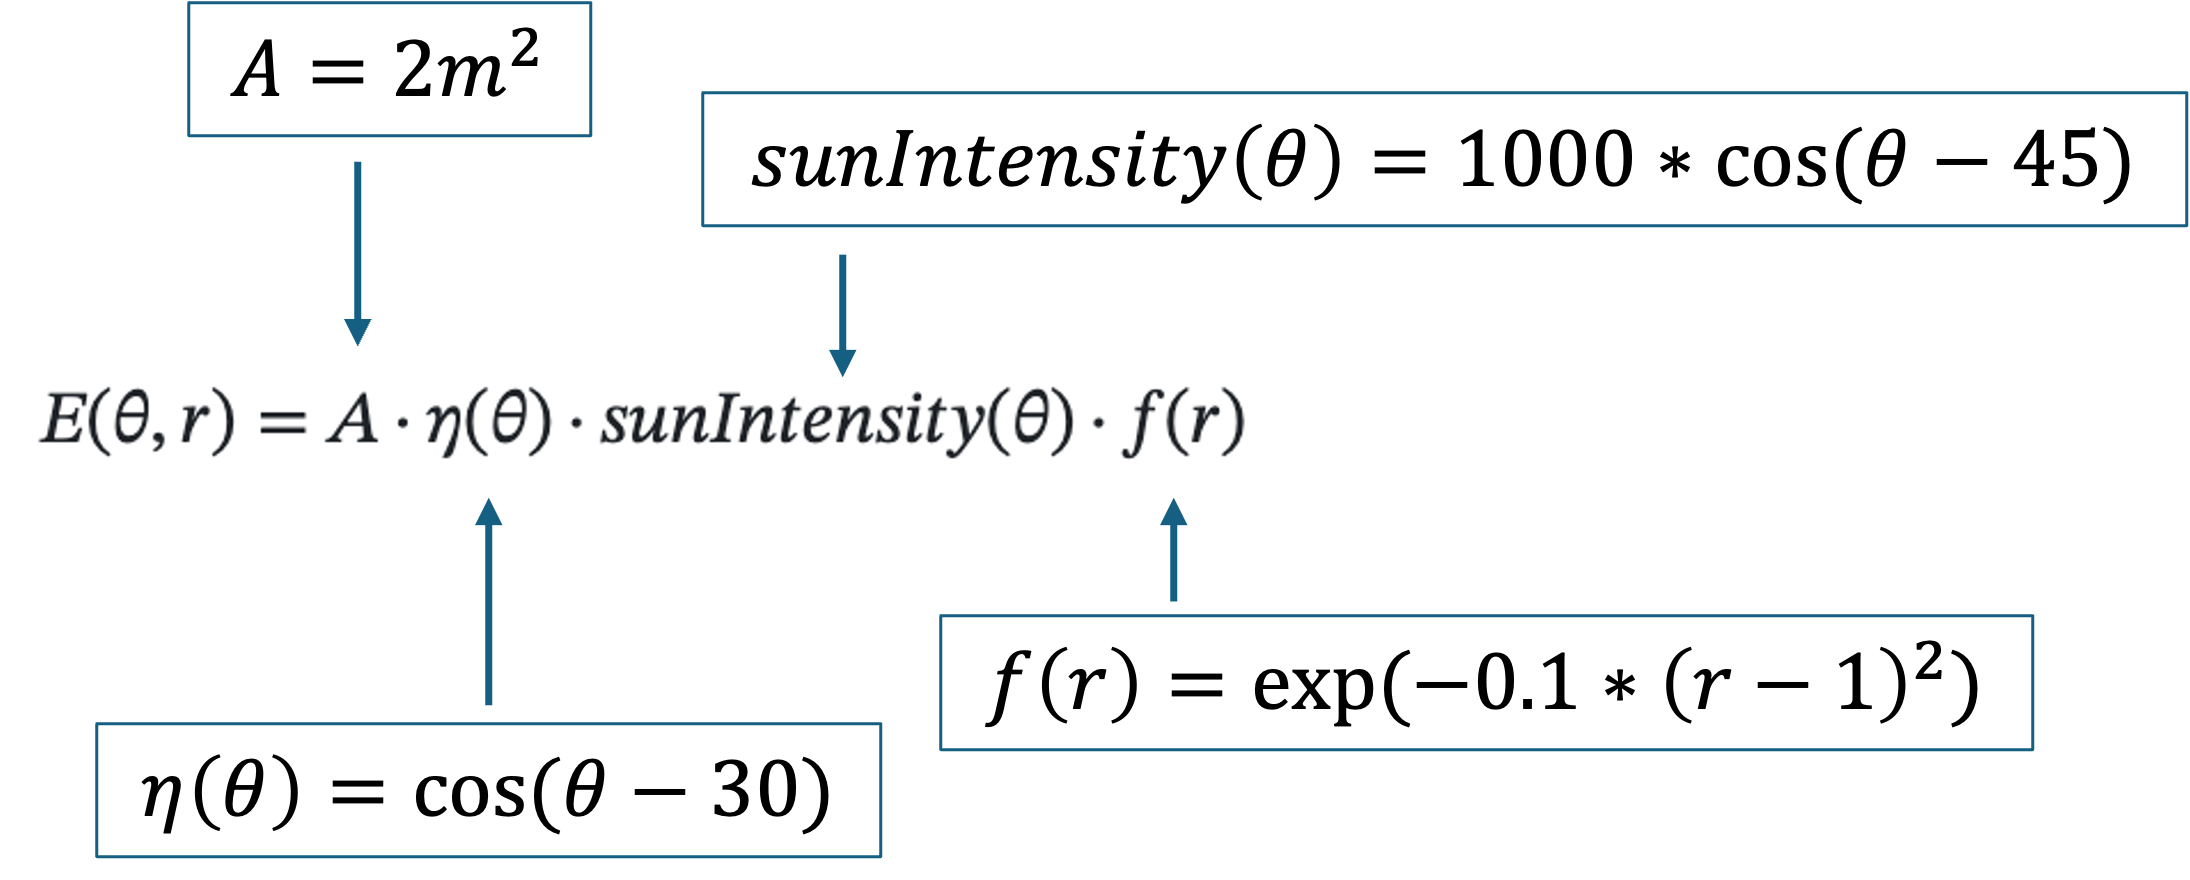

%% Task 1: Define the Objective Function

% panel area (m^2), fixed
A = 2;

% efficiency drops off the further tilt angle gets from 30 degrees
nu = @(theta) cosd(theta - 30);

% sunlight intensity peaks around a 45 degree tilt
sun_intensity = @(theta) 1000 .* cosd(theta - 45);

% shape efficiency - best around r = 1, drops off on either side
fr = @(r) exp(-0.1 .* (r - 1).^2);

% time factor: 0 at 6am, peaks at noon, back to 0 at 6pm
% (just a simple downward parabola centered on t = 12)
time_factor = @(t) 1 - ((t - 12)./6).^2;

% put it all together
energy_function = @(theta,r,t) A .* nu(theta) .* sun_intensity(theta) .* fr(r) .* time_factor(t);

## Task 2: Implement the Optimization Function

The [optimization problem](https://www.mathworks.com/help/releases/R2026a/optim/ug/problem-based-workflow.html) solves for the **Maximum Energy Output**. 

This sets up the optimization problem to search for the θ, r, and t that maximize energy output, within the bounds given above.

%% Task 2: Implement the Optimization Function

solar_problem = optimproblem("ObjectiveSense","maximize");


By defining the optimization variables Tilt Angle (theta), Aspect Ratio (r) & time of day (t) the solver finds the highest energy output given the fixed constraints.

In Model 3, the time of day variable (t), is added to the constraints. 

- Constraint for Tilt Angle: $0\degree \le \theta \le 90\degree$

- Constraint for Aspect Ratio: $0\ldotp 5\le r\le 4$ 

- Constraint for Time of Day: $6\le t\le 18$

Note: The solver uses radian values instead of degrees. Multiplying inside the cosine function with pi/180 convert the theta values from degrees to radians.

% Step 2: Define Optimization Variables

% optimization variables and their bounds
theta = optimvar("theta","LowerBound",0,"UpperBound",90);
r = optimvar("r","LowerBound",0.5,"UpperBound",4);
t = optimvar("t","LowerBound",6,"UpperBound",18);

% optimization variables doesn't support cosd/sind, so converting to radians manually
nu_objective = cos((theta - 30) .* pi/180);
sun_intensity_objective = 1000 .* cos((theta - 45) .* pi/180);
fr_objective = exp(-0.1 .* (r - 1).^2);
time_factor_objective = 1 - ((t - 12)./6).^2;

energy_objective = A .* nu_objective .* sun_intensity_objective .* fr_objective .* time_factor_objective;
solar_problem.Objective = energy_objective;

% initial guess to start the solver from
initial_guess.theta = 45;
initial_guess.r = 2;
initial_guess.t = 10;

[solution,max_energy] = solve(solar_problem,initial_guess);


Solving problem using fmincon.

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



optimal_theta = solution.theta;
optimal_ratio = solution.r;
optimal_time = solution.t;
optimal_energy = max_energy;

## Task 3: Output the Results

**Plot E(θ, r, t)** to visualize the energy as a surface plot using `meshgrid` and [surf](https://www.mathworks.com/help/releases/R2026a/matlab/ref/surf.html). Plot the optimal tilt angle, aspect ratio & time of day corresponding to the maximum energy output onto the grid; the absolute maximum of the surface plot should align with the optimal point. Finally, print the optimal tilt angle, aspect ratio & time of day and the Maximum energy output.

The surface plot shows energy output as a function of tilt angle and aspect ratio, with time held at its optimized value.

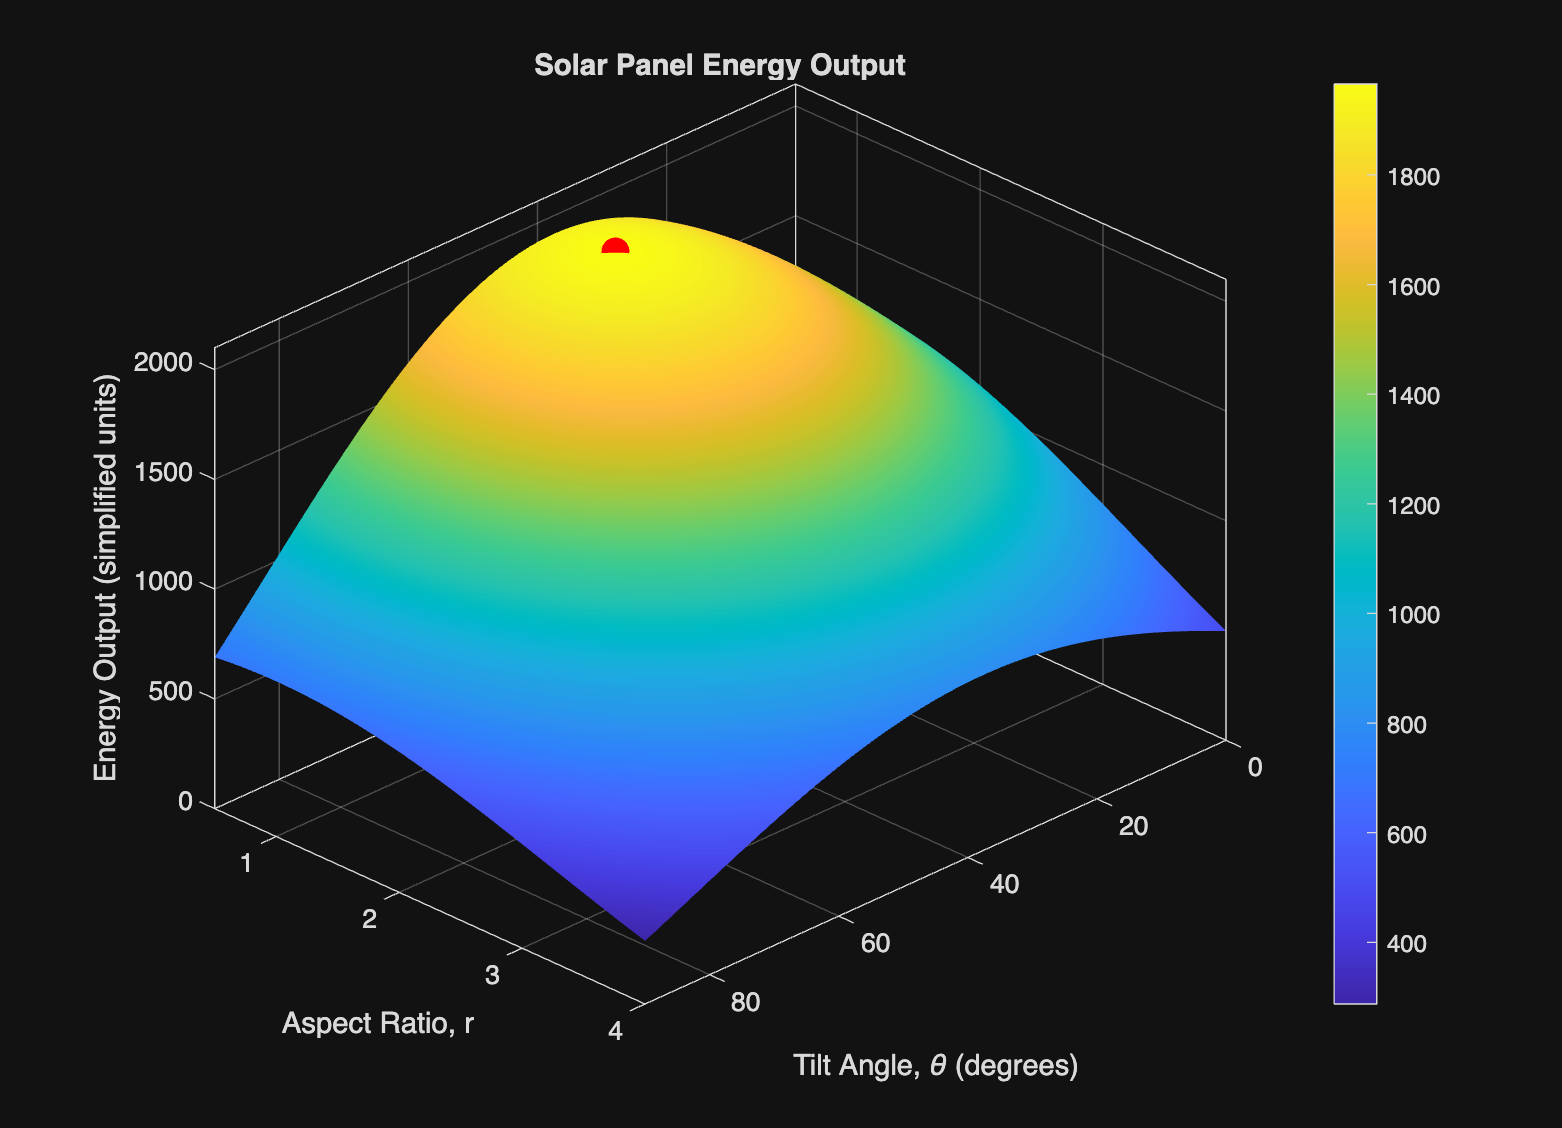

%% Task 3: Output the Results

theta_values = 0:1:90;
r_values = 0.5:0.05:4;

% make sure the exact optimal point actually shows up on the grid
theta_values = sort(unique([theta_values optimal_theta]));
r_values = sort(unique([r_values optimal_ratio]));

[theta_grid,r_grid] = meshgrid(theta_values,r_values);

% time fixed at the optimized value here
energy_grid = energy_function(theta_grid,r_grid,optimal_time);
optimal_energy_plot = energy_function(optimal_theta,optimal_ratio,optimal_time);

figure("Position",[100 100 900 650]);
surf(theta_grid,r_grid,energy_grid);
shading interp

xlabel("Tilt Angle, \theta (degrees)")
ylabel("Aspect Ratio, r")
zlabel("Energy Output (simplified units)")
title("Solar Panel Energy Output")

colorbar
grid on
box on

xlim([0 90])
ylim([0.5 4])
zlim([0 2100])

view(135,27)
pbaspect([1.35 1 0.85])

% mark where the optimal point actually lands
hold on
plot3(optimal_theta,optimal_ratio,optimal_energy_plot,"ro","MarkerSize",9,"MarkerFaceColor","r","LineWidth",1.5)
hold off

## Task 4: Plot Energy Output Over Time

Shows how energy changes across the day once tilt angle and aspect ratio are locked at their optimal values.

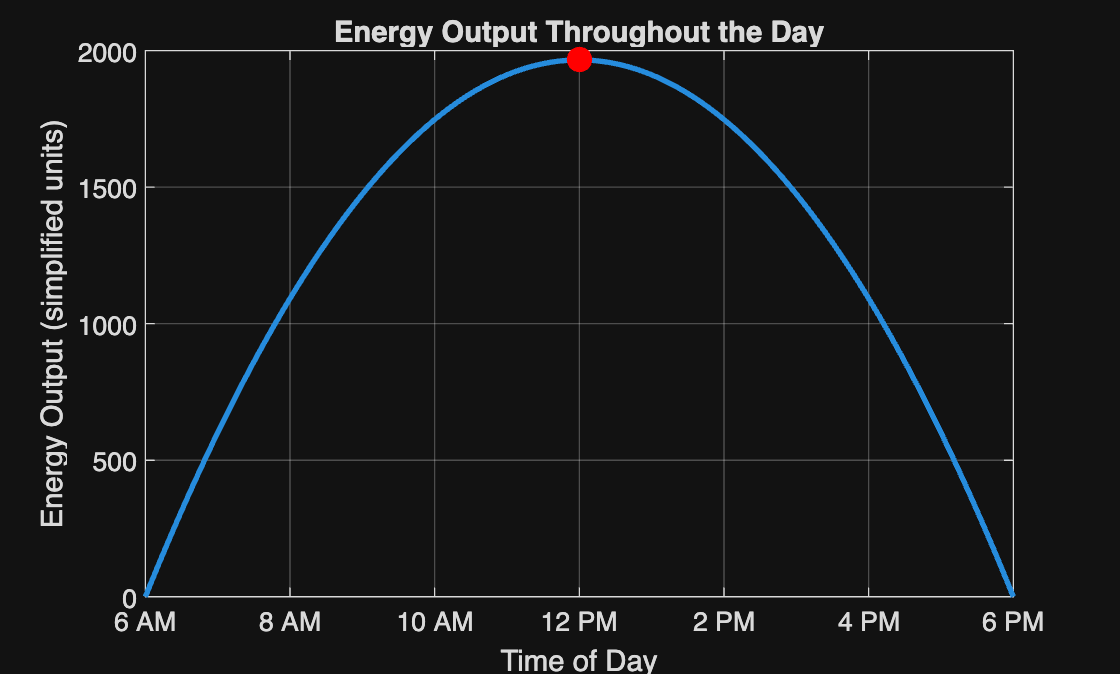

%% Task 4: Plot Energy Output Over Time

time_values = 6:0.1:18;
energy_over_time = energy_function(optimal_theta,optimal_ratio,time_values);

figure
plot(time_values,energy_over_time,"LineWidth",2);
hold on
plot(optimal_time,optimal_energy,"ro","MarkerSize",9,"MarkerFaceColor","r");
hold off

xlabel("Time of Day")
ylabel("Energy Output (simplified units)")
title("Energy Output Throughout the Day")

grid on
box on
xlim([6 18])
xticks(6:2:18)
xticklabels({"6 AM","8 AM","10 AM","12 PM","2 PM","4 PM","6 PM"});

## Task 5: Print the Results

%% Task 5: Print Results

fprintf("\nOptimization Results\n");


Optimization Results


fprintf("----------------------\n");

----------------------


fprintf("Optimal tilt angle: %.2f degrees\n", optimal_theta);

Optimal tilt angle: 37.50 degrees


fprintf("Optimal aspect ratio: %.2f\n", optimal_ratio);

Optimal aspect ratio: 1.00


fprintf("Optimal time: %.2f hours\n", optimal_time);

Optimal time: 12.00 hours


fprintf("Maximum energy output: %.2f energy units\n", optimal_energy);

Maximum energy output: 1965.93 energy units


## Interpretation of Results

**Summary**

The optimizer lands on a tilt angle of about 37.5°, an aspect ratio right around 1, and a time of 12 PM.

The tilt angle ends up between 30° and 45° because two different angle-dependent terms are pulling in slightly different directions panel efficiency peaks near 30°, but sunlight intensity peaks near 45°. The solver settles somewhere in between since that's where the product of the two is largest.

Aspect ratio comes out to basically 1, which makes sense given the shape efficiency function is built to peak exactly at r = 1.

Noon being optimal isn't surprising either the time factor is just a parabola centered on t = 12, so it's maxed out there by construction.

**Limitations**

This model is pretty simplified and skips a lot of what actually affects real solar panels — weather, cloud cover, seasonal changes, geographic location, temperature, shading from nearby trees or buildings, and solar azimuth are all left out. The time factor is also just a rough parabola rather than anything based on real irradiance data. On top of that, treating time as something we're "optimizing" is a little odd conceptually, since it's really an environmental condition and not a design choice for the panel itself.

**Next Steps**

Swapping the simplified time function for real solar irradiance data would be the most useful next step. Beyond that, the model could be extended to account for shading, seasonal sun angles, geographic location, or panel azimuth. It'd also be worth optimizing for total energy produced over a full day rather than just the single moment when instantaneous output is highest.